clear; close all;
epochEarlystop = 60;
for i = 3:10
    i
    folderName_R_Diff{i} = sprintf('trainRecord_anti_force/trainRecord_R_%d_anti_force',i);
    dataFile_R_Diff{i} = load(sprintf('data/%s/moduleResult.mat',folderName_R_Diff{i}));
end

for i = 1:10
    i
    folderName_R_5_rep{i} = sprintf('trainRecord_R_5_anti_rep/rep%d',i);
    dataFile_R_5_rep{i} = load(sprintf('data/%s/moduleResult.mat',folderName_R_5_rep{i}));
end



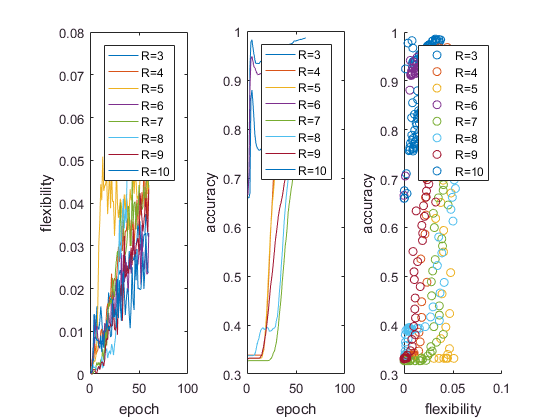

%% plot accuracy/flexibility v.s. epoch
legendNames = {}; 
for i = 3:10
    legendNames{i-2} = sprintf('R=%d',i);
end


figure;
title('R=3 to 10');
subplot(1,3,1);
for i = 3:10
    plot(dataFile_R_Diff{i}.flexibility); hold on;
end
legend(legendNames);
ylabel('flexibility');
xlabel('epoch');
subplot(1,3,2);
for i = 3:10
    plot(dataFile_R_Diff{i}.acc(1:epochEarlystop)); hold on;
end
legend(legendNames);
ylabel('accuracy');
xlabel('epoch');
subplot(1,3,3);
for i = 3:10
    scatter(dataFile_R_Diff{i}.flexibility,dataFile_R_Diff{i}.acc(1:epochEarlystop)); hold on;
end
legend(legendNames);
ylabel('accuracy');
xlabel('flexibility');

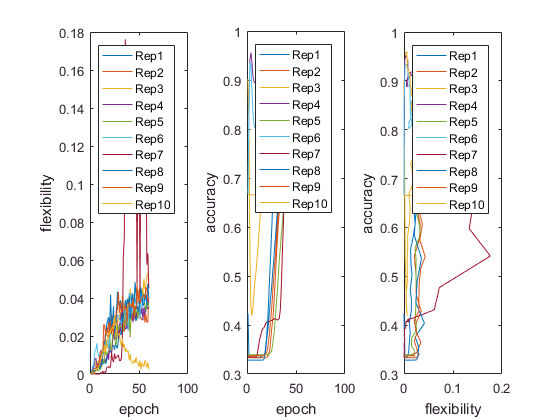

legendNamesR5Rep = {};
for i = 1:10    
    legendNamesR5Rep{i} = sprintf('Rep%d',i);
end

figure;
title('R= 5, 10 reps');
subplot(1,3,1);
for i = 1:10
    plot(dataFile_R_5_rep{i}.flexibility); hold on;
end
legend(legendNamesR5Rep);
ylabel('flexibility');
xlabel('epoch');
subplot(1,3,2);
for i = 1:10
    plot(dataFile_R_5_rep{i}.acc(1:epochEarlystop)); hold on;
end
legend(legendNamesR5Rep);
ylabel('accuracy');
xlabel('epoch');
subplot(1,3,3);
for i = 1:10
    scatter(dataFile_R_5_rep{i}.flexibility, dataFile_R_5_rep{i}.acc(1:epochEarlystop)); hold on;
end
legend(legendNamesR5Rep);
ylabel('accuracy');
xlabel('flexibility');

clear; close all;
epochEarlystop = 60;

for i = 1:120
    i
    folderName_R_5_rep_120_diff_data{i} = sprintf('r_5_rep_120_diff_data/%d',i);
    dataFile_R_5_rep_120_diff_data{i} = load(sprintf('data/%s/moduleResult.mat',folderName_R_5_rep_120_diff_data{i}));
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

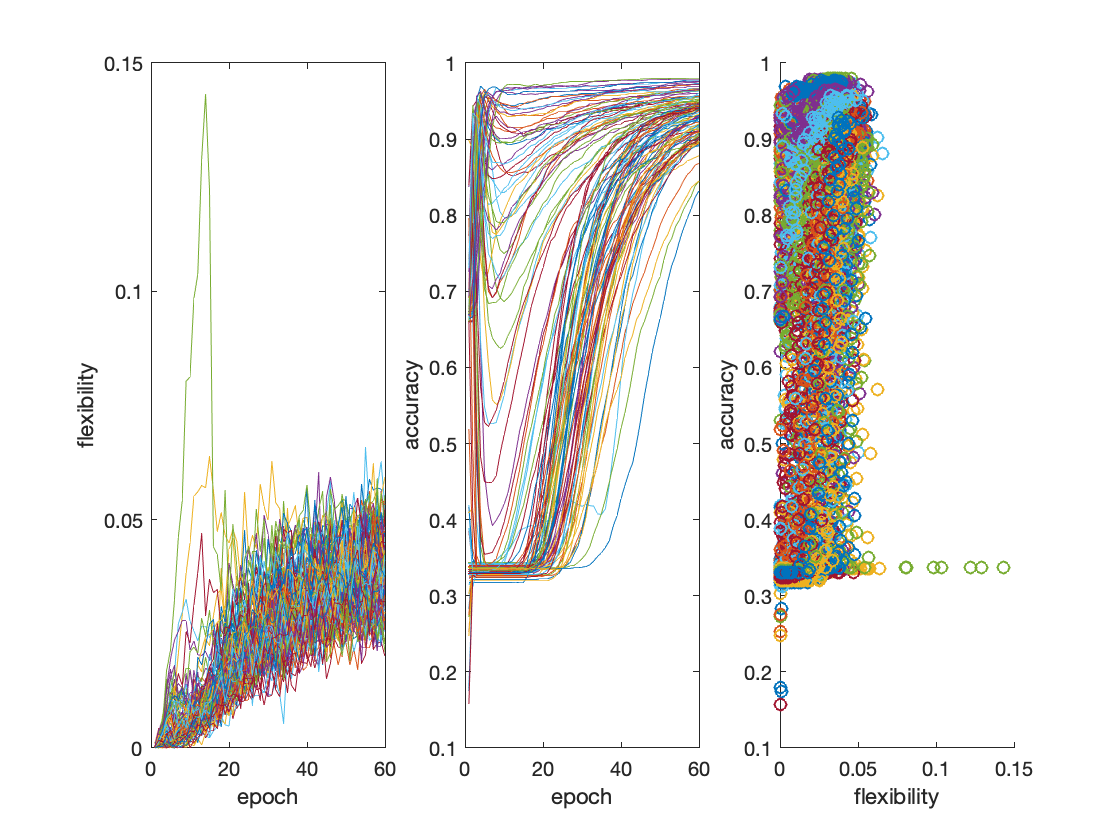


figure;
subplot(1,3,1);
for i = 1:120
    plot(dataFile_R_5_rep_120_diff_data{i}.flexibility); hold on;
end
ylabel('flexibility');
xlabel('epoch');
subplot(1,3,2);
for i = 1:120
    plot(dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop)); hold on;
end
ylabel('accuracy');
xlabel('epoch');
subplot(1,3,3);
for i = 1:120
    scatter(dataFile_R_5_rep_120_diff_data{i}.flexibility, dataFile_R_5_rep_120_diff_data{i}.acc(1:epochEarlystop)); hold on;
end
ylabel('accuracy');
xlabel('flexibility');